Ex 1.1 - 1.3

test_image = reshape((11:100), 10, 9);

get_patch(test_image, 3, 3, 1)

ans =     22    32    42
    23    33    43
    24    34    44


get_patch(test_image, 3, 3, 2)

ans =     11    21    31    41    51
    12    22    32    42    52
    13    23    33    43    53
    14    24    34    44    54
    15    25    35    45    55


get_patch(test_image, 3, 3, 3)

Error using get_patch (line 14)
Patch outside image borders

Ex 1.4 - 1.6

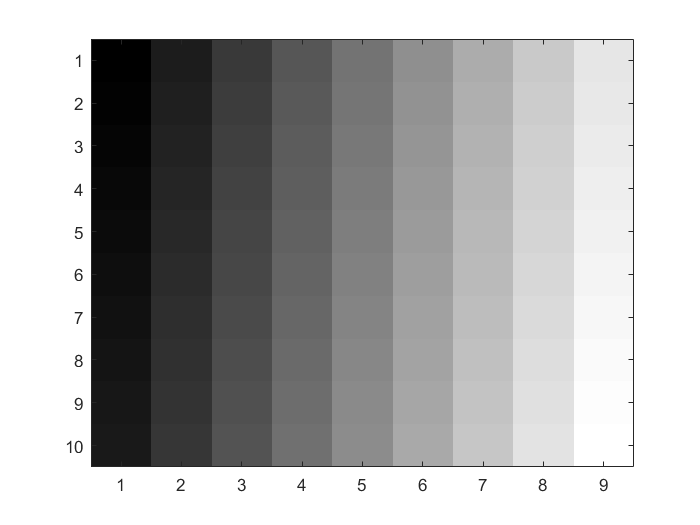

test_image = reshape((11:100), 10, 9);

std = 4.0;

figure()
imagesc(test_image), colormap gray

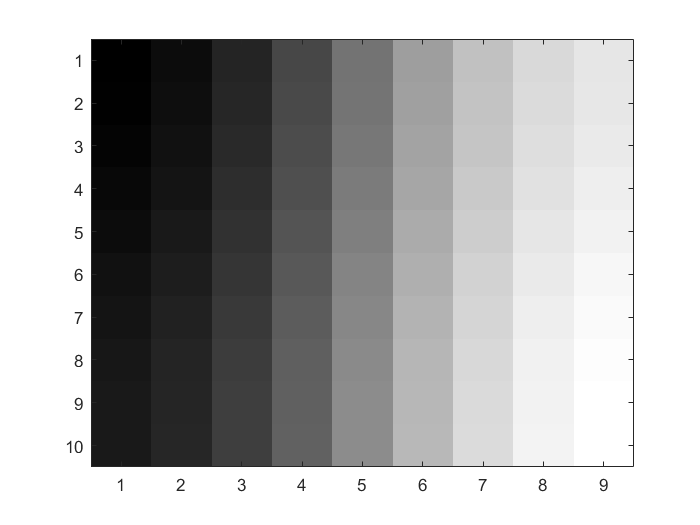


figure()
filtered_image = gaussian_filter(test_image, std);
imagesc(filtered_image), colormap gray

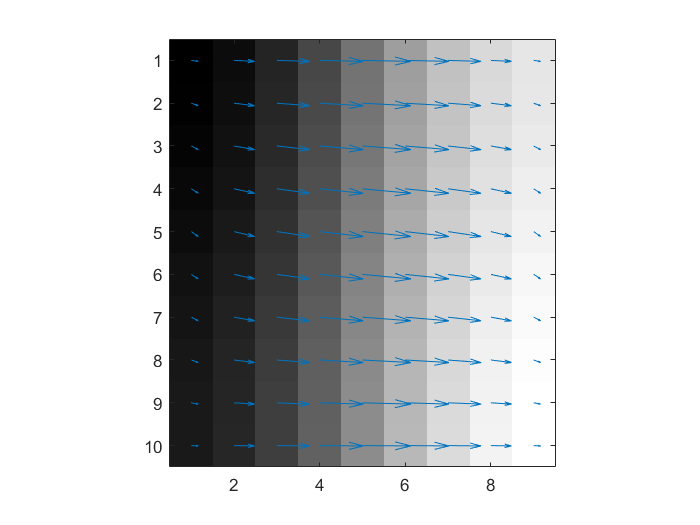


figure()
[grad_x, grad_y] = gaussian_gradients(test_image, std);
imagesc(filtered_image), colormap gray
axis image
hold on
quiver(grad_x, grad_y)
hold off

Ex 1.7

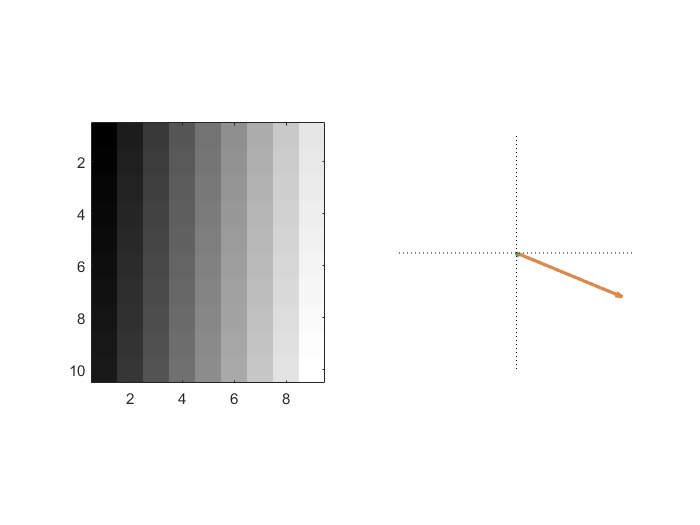

test_image = reshape((11:100), 10, 9);

figure()
plot_bouquet(test_image, 4.0)

Ex 1.8

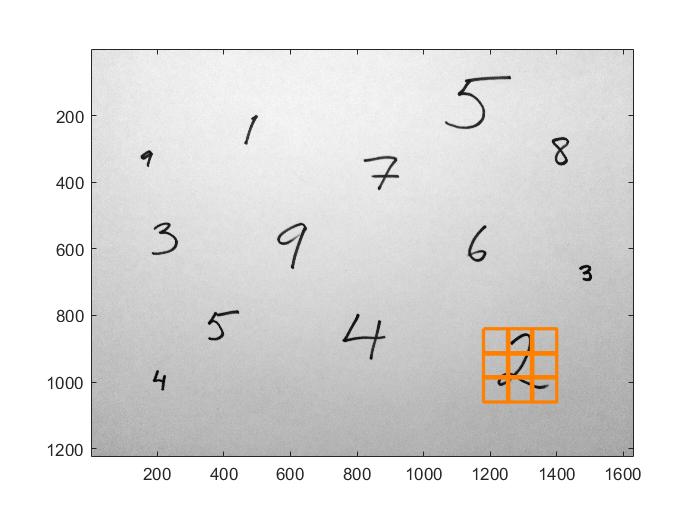

raw_image = imread('paper_with_digits.png');  % uint8 [0, 255] or uint16 [0, 65535]

raw_image = mean(raw_image, 3);
test_image = im2double(raw_image); % Convert to double

position = [1290, 950];
radius = 38;

region_centres = place_regions(position, radius);
plot_squares(test_image, region_centres, radius)

Ex. 1.9 - 1.12

prepare_digits;

classify_all_digits;

I am digit 0
Classified as 0
I am digit 0
Classified as 9
I am digit 0
Classified as 9
I am digit 0
Classified as 0
I am digit 0
Classified as 0
I am digit 1
Classified as 1
I am digit 1
Classified as 2
I am digit 1
Classified as 9
I am digit 1
Classified as 1
I am digit 1
Classified as 1
I am digit 2
Classified as 2
I am digit 2
Classified as 6
I am digit 2
Classified as 3
I am digit 2
Classified as 2
I am digit 2
Classified as 4
I am digit 3
Classified as 3
I am digit 3
Classified as 9
I am digit 3
Classified as 3
I am digit 3
Classified as 3
I am digit 3
Classified as 3
I am digit 4
Classified as 2
I am digit 4
Classified as 4
I am digit 4
Classified as 6
I am digit 4
Classified as 4
I am digit 4
Classified as 4
I am digit 5
Classified as 5
I am digit 5
Classified as 6
I am digit 5
Classified as 5
I am digit 5
Classified as 3
I am digit 5
Classified as 5
I am digit 6
Classified as 6
I am digit 6
Classified as 6
I am digit 6
Classified as 6
I am digit 6
Classified as 6
I am digit 6
C

Ex. 1.13

prepare_digits;

raw_image = imread('paper_with_digits.png');  % uint8 [0, 255] or uint16 [0, 65535]

raw_image = mean(raw_image, 3);
image = im2double(raw_image); % Convert to double

locations = [480, 240, 19, 1; 1290, 950, 38, 2; 220, 570, 24, 3; 820, 875, 32, 4; 1160, 165, 38, 5; 170, 330, 11, 9]; %1, 2, 3, 4, 9

%region_centres = place_regions(position, radius);
%plot_squares(image, region_centres, radius)

for index = 1:6

    compVal = -1;

    position = locations(index, 1:2);
    radius = locations(index, 3);

    descriptor = gradient_descriptor(image, position, radius);

    for i = 1: 100
        cVal = sum(abs(descriptor - digits_training(i).descriptor));
        if (compVal == -1 || compVal > cVal)
            compVal = cVal;
            label = digits_training(i).label;
        end
    end

    if (label == locations(index, 4))
        disp(['Success, I am a ' num2str(label)])
    else
        disp(['Failed, I am not a ' num2str(label) ', I am a ' num2str(locations(index, 4))])
    end
end

Failed, I am not a 8, I am a 1


Success, I am a 2
Success, I am a 3
Success, I am a 4
Success, I am a 5


Failed, I am not a 4, I am a 9


The classification of 4 of the given 6 images has succeeded. 

To set the parameter radius automatically it would be necessary to use edge detection with non-maximum supression. Once the edge is closed in itself the digit would be completly visible and the radius can be determined. 

Ex. 1.14

raw_image = imread('paper_with_digits.png');  % uint8 [0, 255] or uint16 [0, 65535]

raw_image = mean(raw_image, 3);
image = im2double(raw_image); % Convert to double

[coords, descriptors] = extractSIFT(image);

matchFeatures(descriptors.', descriptors.', 'MatchThreshold', 100, 'MaxRatio', 0.7)

ans = 669×2 uint32 matrix
    1    1
    2    2
    3    3
    4    4
    5    5
    6    6
    7    7
    8    8
    9    9
   10   10


Ex 1.15

load church_data.mat
load manual_labels.mat

for i = 1:10
    raw_image = imread(['church' num2str(i) '.jpg']);  % uint8 [0, 255] or uint16 [0, 65535]
    
    raw_image = mean(raw_image, 3);
    image = im2double(raw_image); % Convert to double
    
    disp(['I am a chruch in ' char(manual_labels(i))])
    
    [label, name] = classify_church(image, feature_collection);
    
    disp(['My features match a church in ' char(name)])
end

I am a chruch in goteborg


My features match a church in goteborg


I am a chruch in kalmar


My features match a church in kalmar


I am a chruch in stockholm


My features match a church in uppsala


I am a chruch in kalmar


My features match a church in kalmar


I am a chruch in uppsala


My features match a church in uppsala


I am a chruch in uppsala


My features match a church in uppsala


I am a chruch in goteborg


My features match a church in goteborg


I am a chruch in lund


My features match a church in lund


I am a chruch in lund


My features match a church in lund


I am a chruch in stockholm


My features match a church in stockholm


9 of 10 images are classified correctly. Merely image "church3" is classified as a church in Uppsala, although the chruch is in Stockholm.